# CosmicRays.mlx

Analyzes data file  6808.2017.0905 from QuarkNet (  [https://quarknet.org/](https://quarknet.org/) ) muon telescope/hodoscope ( [https://www.i2u2.org/elab/cosmic/analysis-lifetime/output.jsp?id=199)](https://www.i2u2.org/elab/cosmic/analysis-lifetime/output.jsp?id=199)) to measure muon lifetime. The telescope comprises a stack of 4 scintillation counters (Channels 1-4 with 1 on top). The vertical separation between successive counters is about 4 cm. A 2-fold coincidence was required (ConReg0: 1F, the 1 means 2-fold, F=1111 hex so enables all counters). Total events 477655, total lines 1706120, gate width 300ns define an coincidence event, just handfuls of orphan rising and falling edges. 

Registers:

ConReg0: 1F 1= 2-fold coincidence, F=1111 enables all counters, higher bits would indicate hardware vetos

ConReg1: 71 71(hex)=112(dec)=1110001

ConReg2: 1E 1E(hex)= 30(dec)=11110=>111101110001=3953(dec)=>window= 39.53 microsec read after trigger

ConReg3: 00 ?

TMCReg0: 00 ?

TMCReg1: 7B =123(dec) 

TMCReg2: 85 =133(dec) Time delay (gate width of coincidence) is Reg2-Reg1=10* 10ns = 100 ns

TMCReg3: 00 ?

The lifetime is determined from the distribution of time differences between successive hits independent of counter using `distributionfitter`. No corrections are applied.

Author: D. Carlsmith

## Import data from text file. The following code was generated using the import tool.

Script for importing data from the following text file: (971,605 lines)

To extend the code to different selected data or a different text file, generate a function instead of a script.

clear

Initialize variables.

filename = './fermilab_test_array_data/6234.2017.1227.0.wd.txt';
%filename = '/Users/duncancarlsmith/Documents/MATLAB/CosmicRays/6122.2018.0814.0.wd.txt';

delimiter = '\t';
startRow = 2;

Format for each line of text:

formatSpec = '%f%f%f%f%f%[^\n\r]';

Open the text file.

fileID = fopen(filename,'r');

Read columns of data according to the format.

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');

Close the text file.

fclose(fileID);

Allocate imported array to column variable names

ID = dataArray{:, 1}; % channel/counter ID in form M.N, M=run, N=1-4 = counter #
Day = dataArray{:, 2};% Date (Julian day)
Rising = dataArray{:, 3};% pulse rising edge time (Julian day)
Falling = dataArray{:, 4};% pulse falling edge time (Julian day)
Width = dataArray{:, 5};% pulse width (ns)

Clear temporary variables

clearvars filename delimiter startRow formatSpec fileID dataArray ans;

## Fix idiosyncrasies in the data

ID number is  site_location.ch so convert to Channel number 1-4

ID0=round(ID(1));
%ID(1:10)
ID=round((ID-ID0)*10);
%ID(1:10)

Falling and rising edges are labeled as in seconds in the data file but that is incorrect. These numbers are fractions of a Julian day, not seconds despite the column label. The number of seconds in a Julian day is 86400. There is a jump in the fraction of a day if the day shifts. If we add say Day to Rising to get rising time in Julian days we will exceed the MATLAB double precision. So first subtract the first Julian day, then add fraction of a day, then convert to monatomic time in seconds.

startday=Day(1);
Day=Day-startday;
Rising = Day+Rising;
start = Rising(1);
Rising = (Rising - start)*86400;
Falling= Day+Falling;
Falling = (Falling - start)*86400;

### Take a look at the data:

Plot rising times to check if monotonic.

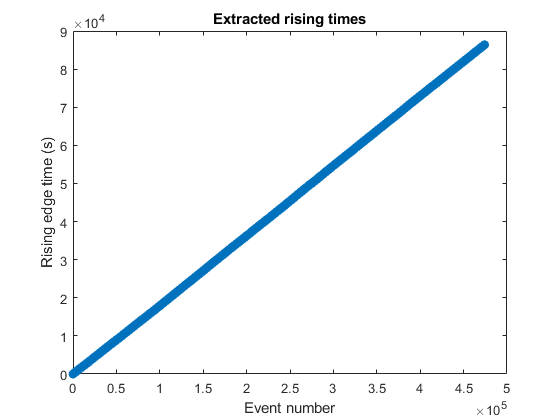

plot(Rising,'o')%;hold on; plot(Falling,'+');hold off
xlabel('Event number');ylabel('Rising edge time (s)')
title('Extracted rising times')

Zoom in

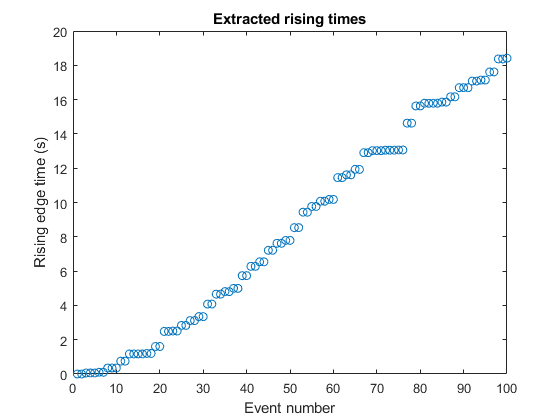

plot(Rising(1:100),'o')%;hold on; plot(Falling,'+');hold off
xlabel('Event number');ylabel('Rising edge time (s)')
title('Extracted rising times')

Histogram the pulse widths. Pulse widths should be of order 30 ns.

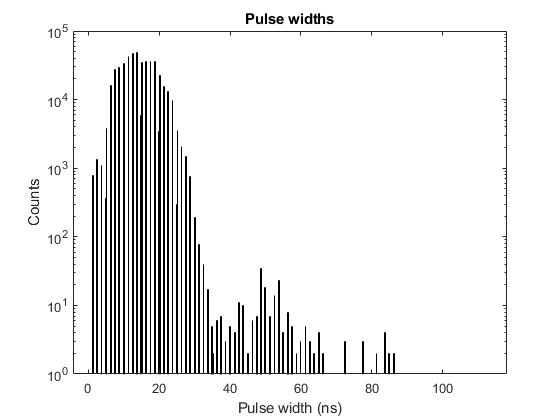

histogram(Width)
set(gca,'YScale','log')
title('Pulse widths')
xlabel('Pulse width (ns)'); ylabel('Counts')

Histogram numbr of counts in each scintillator.  If the counters are equally efficient, have equal area, and have similar noise rates, the counts should all be similar to each other.

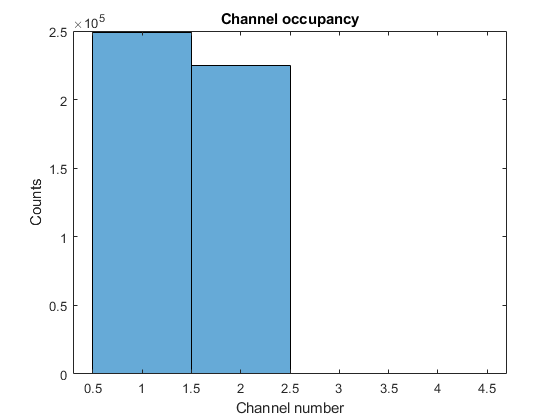

figure
histogram(ID)
title('Channel occupancy')
xlabel('Channel number'); ylabel('Counts')

Histogram difference between successive times (independent of channel) for differences less than 1 microsecond.

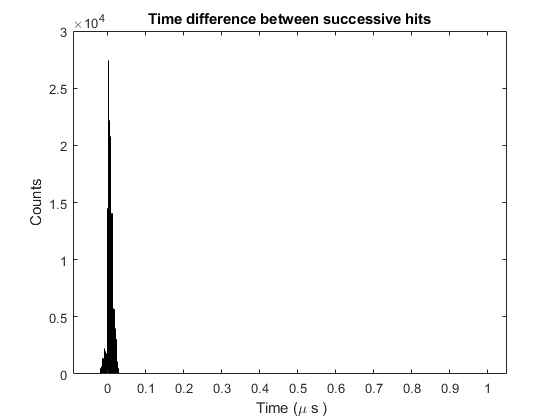

RisingDiff=diff(Rising);
IDDiff = diff(ID);% difference in integer (1-4) ID numbers 
histogram(10^6*RisingDiff(abs(RisingDiff)<10^(-6)))
%set(gca,'YScale','log')
title('Time difference between successive hits')
xlabel(' Time (\mu s )');ylabel('Counts')

The time differences are typically small and correspond to events in which the muon does not stop. There is a tail with time differences extending over microseconds suggestive of events in which a muon stopped and then decayed. Zoom in.

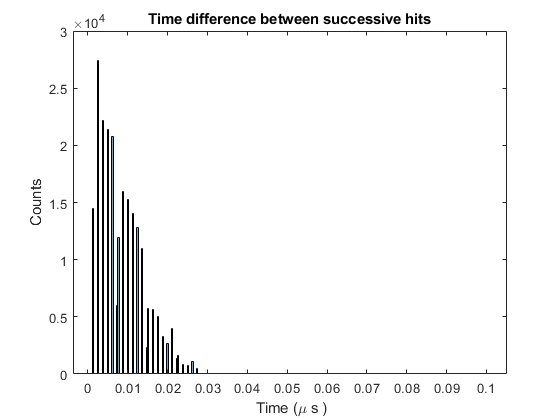

histogram(10^6*RisingDiff( RisingDiff<10^(-7)&RisingDiff>0 ) )
title('Time difference between successive hits')
xlabel(' Time (\mu s )');ylabel('Counts')

The typical time difference is +20 ns. The physical time difference is much less (inches over light speed) so the dfference may concern cable lengths. Also, a 2nd hit in the same counter must be some pulse width time later.

Histogram ID difference

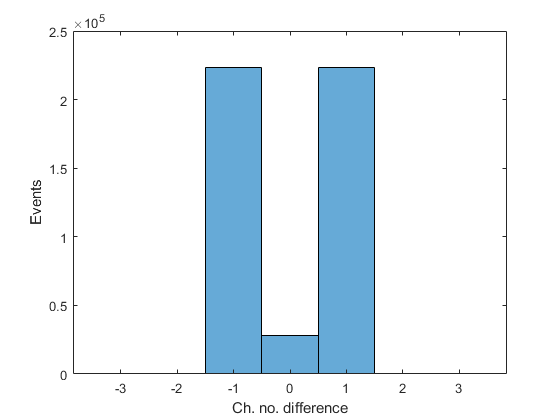

histogram(IDDiff); xlabel('Ch. no. difference');ylabel('Events')

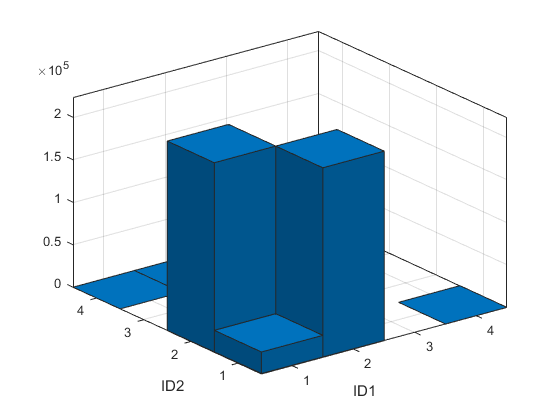

figure
histogram2(ID,circshift(ID,-1));xlabel('ID1');ylabel('ID2')

Select data with difference  less than 100 microsec (~50 lifetimes) and >100 ns.

mask = RisingDiff<100*10^(-6)&RisingDiff>100*10^(-9);
LifeTime=RisingDiff(mask);

Plot selected data

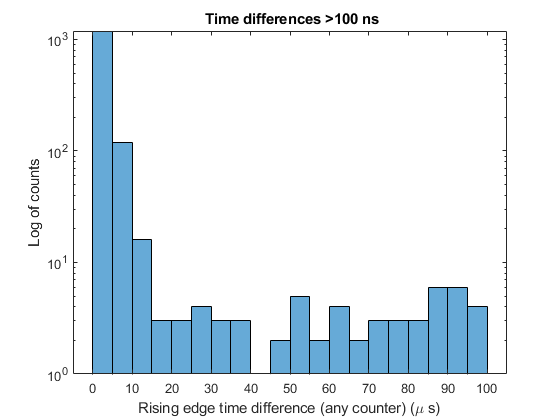

figure
histogram(10^6*LifeTime )
set(gca,'YScale','log')
title(' Time differences >100 ns')
xlabel('Rising edge time difference (any counter) (\mu s)');ylabel('Log of counts')

There is evidence of an exponential muon decay signal with a time frame of a couple of microsec and a tail due to random coincidences.

Select the muonic and nonmuonic parts

figure
maskmuonic = RisingDiff<10^(-5)&RisingDiff>100*10^(-9);
Lifetime = RisingDiff(maskmuonic);

What fraction of the data did we just select? Expect order few MeV range-out-in-scintillator range over GeV total energy distribution range or ~ 1e-3.

DataFraction=length(LifeTime)/length(RisingDiff)

DataFraction = 0.0029

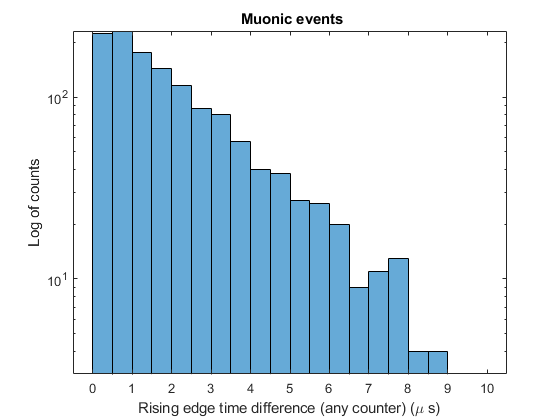

maskbackground = RisingDiff<10^(-4)&RisingDiff>10^(-5);
histogram(10^6*RisingDiff(maskmuonic))
set(gca,'YScale','log')
title(' Muonic events')
xlabel('Rising edge time difference (any counter) (\mu s)');ylabel('Log of counts')

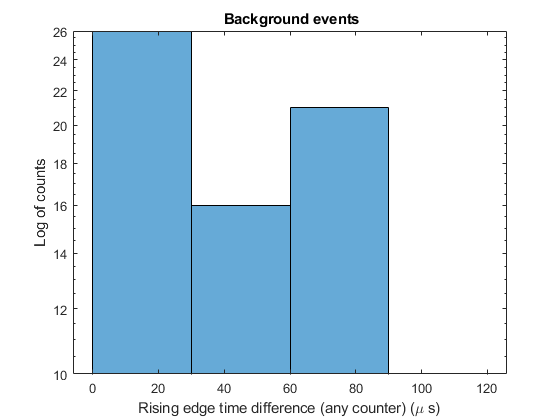

histogram(10^6*RisingDiff(maskbackground))
set(gca,'YScale','log')
title(' Background events')
xlabel('Rising edge time difference (any counter) (\mu s)');ylabel('Log of counts')

## Fit for the muon lifetime

One way to fit to a single exponential to the time distribution is using distribution fitter. See [https://www.mathworks.com/help/stats/model-data-using-the-distribution-fitting-tool.html](https://www.mathworks.com/help/stats/model-data-using-the-distribution-fitting-tool.html).

Select LifeTime as the data. The distributions available to fit depend on the data. Create an exclusion rule to exclude data <=0. Then the exponential distribution will be an option, otherwise not.

The fit is  based on maximum likelihood, not on histogramming and fitting weighted histogram counts. See [https://www.mathworks.com/help/stats/examples/curve-fitting-and-distribution-fitting.html](https://www.mathworks.com/help/stats/examples/curve-fitting-and-distribution-fitting.html) and [https://www.mathworks.com/help/stats/mle.html](https://www.mathworks.com/help/stats/mle.html) .

The distribution fitter too permits export of the data selection and fit code to a function which is appended to this script.

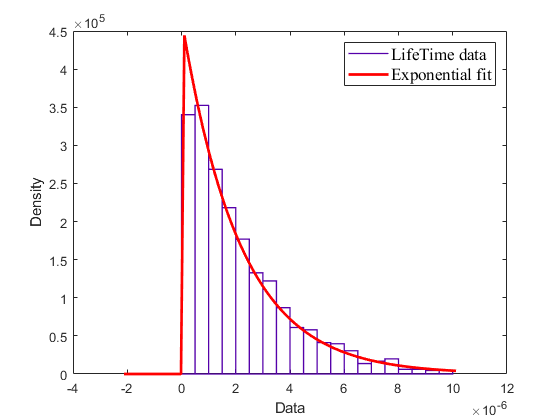

pd1 =   ExponentialDistribution

  Exponential distribution
    mu = 2.1424e-06   [2.031e-06, 2.26327e-06]


LifeTime=RisingDiff(maskmuonic);
pd1 = createFit(LifeTime)

The fitted value is

meanmu=pd1.mu

meanmu = 2.1424e-06

We find a lifetime close to expectation (2.1969811(22) microseconds). The standard error is

stdmu=sqrt(pd1.ParameterCovariance)

stdmu = 5.9170e-08

The deviation from expectation in stds is

muexpected= 2.1969811*10^(-6);
mudeviation= (meanmu-muexpected)/stdmu

mudeviation = -0.9224

function pd1 = createFit(LifeTime)
%CREATEFIT    Create plot of datasets and fits
%   PD1 = CREATEFIT(LIFETIME)
%   Creates a plot, similar to the plot in the main distribution fitter
%   window, using the data that you provide as input.  You can
%   apply this function to the same data you used with dfittool
%   or with different data.  You may want to edit the function to
%   customize the code and this help message.
%
%   Number of datasets:  1
%   Number of fits:  1
%
%   See also FITDIST.

% This function was automatically generated on 30-Sep-2018 16:55:53

% Output fitted probablility distribution: PD1

% Data from dataset "LifeTime data":
%    Y = LifeTime

% Force all inputs to be column vectors
LifeTime = LifeTime(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "LifeTime data"
[CdfF,CdfX] = ecdf(LifeTime,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(LifeTime,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'LifeTime data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "Exponential fit"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('exponential',[ 1.911531296385e-06])
pd1 = fitdist(LifeTime, 'exponential');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Exponential fit';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontName', 'times', 'FontSize', 12.6, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

end